%% =========================================================================
%  脚本名称: 3-DOF 机械臂动力学推导与仿真控制主程序
%  功能描述: 
%     1. 基于 Lagrange 方法推导动力学方程 (M, C, G) 并生成函数文件
%     2. 生成多点笛卡尔空间轨迹 (五次多项式插值)
%     3. 调用 Simulink 模型进行闭环仿真
%     4. 导出仿真数据与结果可视化
%  对应模型: Inverse_solution.slx
% =========================================================================



% --- 【初始化命令】 ---
clear;          % 1. 清空工作区：删除所有之前的变量，防止干扰
clc;            % 2. 清空命令行：让输出窗口变干净
close all;      % 3. 关闭图窗：关闭之前的 plot 图
bdclose('all'); % 4. (推荐) 关闭所有 Simulink 模型：防止模型在后台缓存导致报错
% ---------------------

%% =========================================================================
%  第一部分：动力学符号推导 (Lagrange Method)
% =========================================================================
disp('========================================');

disp('   STEP 1: 动力学方程符号推导');

   STEP 1: 动力学方程符号推导


disp('========================================');


% --- 1.1 定义符号变量 ---
syms q1 q2 q3 real          % 关节角度
syms dq1 dq2 dq3 real       % 关节角速度
syms ddq1 ddq2 ddq3 real    % 关节角加速度
syms g real                 % 重力加速度

% 定义物理参数 (连杆质量、长度、基座高度)
syms m1 m2 m3 real  
syms a2 a3 real     
syms d1 real        

% 惯性张量 (简化模型：仅保留主对角线分量 Izz)
syms Izz1 Izz2 Izz3 real 

% --- 1.2 D-H 变换矩阵定义 ---
% 采用标准 D-H 参数: [theta, d, a, alpha]
DH = @(th, d, a, alp) [ ...
    cos(th), -sin(th)*cos(alp),  sin(th)*sin(alp), a*cos(th);
    sin(th),  cos(th)*cos(alp), -cos(th)*sin(alp), a*sin(th);
    0,        sin(alp),          cos(alp),         d;
    0,        0,                 0,                1];

% 建立各连杆变换矩阵
T01 = DH(q1, d1, 0, pi/2);  % Base -> Link 1
T12 = DH(q2, 0, a2, 0);     % Link 1 -> Link 2
T23 = DH(q3, 0, a3, 0);     % Link 2 -> Link 3

% 前向运动学：计算相对于基座的变换矩阵
T02 = T01 * T12;
T03 = T02 * T23;

% --- 1.3 质心位置与雅可比矩阵 ---
% 假设质心位于连杆几何中心
pc1_local = [0; 0; 0; 1];       % Link 1 质心 (假设位于原点)
pc2_local = [-a2/2; 0; 0; 1];   % Link 2 质心
pc3_local = [-a3/2; 0; 0; 1];   % Link 3 质心

% 将质心转换到基座坐标系
P_cm1 = T01 * pc1_local;
P_cm2 = T02 * pc2_local;
P_cm3 = T03 * pc3_local;

% 提取位置向量 (前3维)
p1 = P_cm1(1:3);
p2 = P_cm2(1:3);
p3 = P_cm3(1:3);

% 计算线性速度雅可比矩阵 Jv (v = Jv * dq)
q_vec = [q1; q2; q3];
Jv1 = jacobian(p1, q_vec);
Jv2 = jacobian(p2, q_vec);
Jv3 = jacobian(p3, q_vec);

% 计算角速度雅可比矩阵 Jw (omega = Jw * dq)
z0 = [0; 0; 1];         % 基座 z 轴
z1 = T01(1:3, 3);       % 关节 1 旋转轴
z2 = T02(1:3, 3);       % 关节 2 旋转轴

Jw1 = [z0, [0;0;0], [0;0;0]];
Jw2 = [z0, z1, [0;0;0]];
Jw3 = [z0, z1, z2];

% --- 1.4 能量计算 (Lagrange Function) ---
dq_vec = [dq1; dq2; dq3];

% 动能 K (平动 + 转动)
K1 = 0.5 * m1 * (Jv1*dq_vec).' * (Jv1*dq_vec) + 0.5 * (Jw1*dq_vec).' * diag([0,0,Izz1]) * (Jw1*dq_vec);
K2 = 0.5 * m2 * (Jv2*dq_vec).' * (Jv2*dq_vec) + 0.5 * (Jw2*dq_vec).' * diag([0,0,Izz2]) * (Jw2*dq_vec);
K3 = 0.5 * m3 * (Jv3*dq_vec).' * (Jv3*dq_vec) + 0.5 * (Jw3*dq_vec).' * diag([0,0,Izz3]) * (Jw3*dq_vec);

K_total = simplify(K1 + K2 + K3);

% 势能 P (P = mgh)
P1 = m1 * g * p1(3);
P2 = m2 * g * p2(3);
P3 = m3 * g * p3(3);
P_total = simplify(P1 + P2 + P3);

% --- 1.5 求解动力学方程系数矩阵 M, C, G ---
fprintf('>> 正在计算惯性矩阵 M(q) (可能需要一点时间)...\n');

>> 正在计算惯性矩阵 M(q) (可能需要一点时间)...


M = jacobian(jacobian(K_total, dq_vec).', dq_vec);
M = simplify(M);

fprintf('>> 正在计算重力向量 G(q)...\n');

>> 正在计算重力向量 G(q)...


G = jacobian(P_total, q_vec).';
G = simplify(G);

fprintf('>> 正在计算科里奥利矩阵 C(q, dq) (基于 Christoffel 符号)...\n');

>> 正在计算科里奥利矩阵 C(q, dq) (基于 Christoffel 符号)...


n = 3;
C = sym(zeros(n, n));
for k = 1:n
    for j = 1:n
        temp = 0;
        for i = 1:n
            % Christoffel 符号公式: c_ijk = 0.5 * (dM_kj/dqi + dM_ki/dqj - dM_ij/dqk)
            c_ijk = 0.5 * (diff(M(k,j), q_vec(i)) + diff(M(k,i), q_vec(j)) - diff(M(i,j), q_vec(k)));
            temp = temp + c_ijk * dq_vec(i);
        end
        C(k,j) = temp;
    end
end
C = simplify(C);

% --- 1.6 数值代入与函数生成 (锁定路径版) ---
fprintf('>> 正在生成 Simulink 可调用的 .m 函数文件...\n');

>> 正在生成 Simulink 可调用的 .m 函数文件...



% 定义数值参数结构体
param.m1 = 2.0; param.m2 = 1.5; param.m3 = 1.0;
param.a2 = 0.4; param.a3 = 0.3;
param.d1 = 0.1;
param.g = 9.81;
% 估算转动惯量 (I = 1/12 * m * L^2)
param.Izz1 = 0.1; 
param.Izz2 = 1/12 * 1.5 * 0.4^2;
param.Izz3 = 1/12 * 1.0 * 0.3^2;

% 符号替换为数值
vars_sym = {m1,m2,m3,a2,a3,d1,g,Izz1,Izz2,Izz3};
vars_num = {param.m1, param.m2, param.m3, param.a2, param.a3, param.d1, ...
            param.g, param.Izz1, param.Izz2, param.Izz3};

M_num = subs(M, vars_sym, vars_num);
G_num = subs(G, vars_sym, vars_num);
C_num = subs(C, vars_sym, vars_num);

% === 构建绝对路径，确保文件生成在 MATLAB Core 目录 ===
% 获取当前脚本所在的文件夹 (MATLAB Core)
core_folder = pwd; 

% 使用 fullfile 构建完整路径，防止路径分隔符错误
path_M = fullfile(core_folder, 'get_M_matrix');
path_C = fullfile(core_folder, 'get_C_matrix');
path_G = fullfile(core_folder, 'get_G_vector');

% 生成函数文件 (指定绝对路径)
matlabFunction(M_num, 'File', path_M, 'Vars', {q1, q2, q3});
matlabFunction(C_num, 'File', path_C, 'Vars', {q1, q2, q3, dq1, dq2, dq3});
matlabFunction(G_num, 'File', path_G, 'Vars', {q1, q2, q3});

fprintf('>> [完成] 动力学函数已生成:\n');

>> [完成] 动力学函数已生成:


fprintf('   📂 位置: %s\n', core_folder);

   📂 位置: C:\Users\ZLX\Documents\v2.0\3-DOF_Robotic_Arm_Dynamics_Simulation_and_Visualization_System\MATLAB Core


fprintf('   📄 文件: get_M_matrix.m, get_C_matrix.m, get_G_vector.m\n\n');

   📄 文件: get_M_matrix.m, get_C_matrix.m, get_G_vector.m



%% =========================================================================
%  第二部分：多点轨迹规划 (Multi-Point Trajectory Planning)
% =========================================================================
disp('========================================');

disp('   STEP 2: 笛卡尔空间多点轨迹规划');

   STEP 2: 笛卡尔空间多点轨迹规划


disp('========================================');


% --- 2.1 设定路点 (Waypoints) ---
% 格式: [x, y, z] (单位: m)
waypoints = [
    0.15,  0.0,  0.1;  % P1 (Home)
    0.25,  0.2,  0.2;  % P2
    0.3,  -0.2,  0.3;  % P3
    0.2,   0.5,  0.4;  % P4 
    0.3,   0.4,  0.1;  % P5
   -0.4,   0.4,  0.1;  % P6
    0.1,   0.2,  0.4;  % P7
   -0.4,   0.2,  0.5;  % P8
   -0.4,   0.2,  0.5;  % P9 (End)
];

% 设定各段运行时间 (单位: s)
segment_times = [1, 1, 1, 1, 1, 1, 1, 2]; 

[num_points, ~] = size(waypoints);
num_segments = num_points - 1;

% 自动补全时间参数检查
if length(segment_times) ~= num_segments
    warning('时间参数与路段数不匹配，自动设为每段 2.0 秒');
    segment_times = ones(1, num_segments) * 2.0;
end

% --- 2.2 IK 可行性预检查 ---
fprintf('>> 正在检查路点工作空间可行性...\n');

>> 正在检查路点工作空间可行性...


for i = 1:num_points
    try
        inverse_kinematics(waypoints(i,1), waypoints(i,2), waypoints(i,3));
    catch
        error('错误：第 %d 个路点 (%.2f, %.2f, %.2f) 无法求解逆运动学！', ...
            i, waypoints(i,1), waypoints(i,2), waypoints(i,3));
    end
end
fprintf('>> 所有路点均在工作空间内。\n');

>> 所有路点均在工作空间内。



% --- 2.3 分段插值与拼接 ---
dt = 0.0001; % 轨迹采样周期
total_t = []; total_q = []; total_pos = [];
current_start_time = 0;

for k = 1:num_segments
    P_start = waypoints(k, :);
    P_end   = waypoints(k+1, :);
    T_seg   = segment_times(k);
    
    % 时间向量 (防止段间重叠)
    if k == 1
        t_seg_vec = 0 : dt : T_seg;
    else
        t_seg_vec = dt : dt : T_seg; 
    end
    
    num_steps = length(t_seg_vec);
    q_seg = zeros(3, num_steps);
    pos_seg = zeros(3, num_steps);
    
    % 五次多项式插值 (Stop-and-Go 模式)
    for i = 1:num_steps
        tau = t_seg_vec(i) / T_seg;
        tau = min(tau, 1); % 饱和限制
        
        % s(t): 0 -> 1, 速度加速度均为0
        s = 10*tau^3 - 15*tau^4 + 6*tau^5;
        P_curr = P_start + (P_end - P_start) * s;
        
        pos_seg(:, i) = P_curr';
        q_seg(:, i) = inverse_kinematics(P_curr(1), P_curr(2), P_curr(3));
    end
    
    % 数据拼接
    total_t = [total_t, current_start_time + t_seg_vec];
    total_q = [total_q, q_seg];
    total_pos = [total_pos, pos_seg];
    current_start_time = current_start_time + T_seg;
end

% --- 2.4 数值微分求速度/加速度 ---
% 使用 gradient 保证边界连续性
total_dq  = zeros(3, length(total_t));
total_ddq = zeros(3, length(total_t));

for j = 1:3
    total_dq(j, :)  = gradient(total_q(j, :), dt);
    total_ddq(j, :) = gradient(total_dq(j, :), dt);
end

% --- 2.5 准备 Simulink 数据 ---
ts_q   = timeseries(total_q.', total_t);
ts_dq  = timeseries(total_dq.', total_t);
ts_ddq = timeseries(total_ddq.', total_t);

% 设置初始状态
x0_robot = [total_q(:,1); 0; 0; 0]; 
assignin('base', 'x0_robot', x0_robot);

fprintf('>> [完成] 轨迹规划完毕，总时长: %.2f 秒\n\n', total_t(end));

>> [完成] 轨迹规划完毕，总时长: 9.00 秒



%% =========================================================================
%  第三部分：Simulink 仿真控制 (已修复)
% =========================================================================
disp('========================================');

disp('   STEP 3: 运行 Simulink 仿真');

   STEP 3: 运行 Simulink 仿真


disp('========================================');


modelName = 'Inverse_solution';

% 1. 加载模型 (简单的错误检查)
try
    load_system(modelName);
    fprintf('>> 模型 "%s" 加载成功。\n', modelName);
catch ME
    fprintf(2, '❌ 模型加载失败: %s\n', ME.message);
    return; % 如果加载都失败了，后面就别跑了
end

>> 模型 "Inverse_solution" 加载成功。



% 2. 运行仿真 (带详细错误捕捉)
disp('⏳ 正在执行仿真...');

⏳ 正在执行仿真...


timerStart = tic;

% 【关键】先保存当前警告状态，然后关闭所有警告
wState = warning('off', 'all'); 

try
    % --- 核心仿真命令 ---
    out = sim(modelName);
    % --------------------
    
    warning(wState); % 恢复警告设置
    elapsedTime = toc(timerStart);
    fprintf('✅ 仿真成功完成，耗时: %.4f 秒\n\n', elapsedTime);
    
catch ME
    % 1. 先恢复警告设置（最重要，否则后续看不到警告）
    warning(wState); 
    
    % 2. 打印主错误信息
    fprintf(2, '❌ 仿真崩溃主提示: %s\n', ME.message);
    
    % 3. 剥洋葱：查看底层的具体错误原因
    if ~isempty(ME.cause)
        fprintf(2, '⬇️⬇️⬇️ 详细错误原因 (请重点看这里) ⬇️⬇️⬇️\n');
        for k = 1:length(ME.cause)
            fprintf(2, '🔴 原因 %d: %s\n', k, ME.cause{k}.message);
        end
        fprintf(2, '⬆️⬆️⬆️ 结束 ⬆️⬆️⬆️\n');
    else
        % 如果没有 cause，尝试打印堆栈位置
        fprintf(2, '   (无子错误原因，错误发生在: %s)\n', ME.stack(1).name);
    end
    
    return; % 停止运行，防止进入第四部分报错
end

✅ 仿真成功完成，耗时: 24.0172 秒



%% =========================================================================
%  第四部分：结果分析与数据导出 (Timeseries 专用版)
% =========================================================================
disp('========================================');

disp('   STEP 4: 结果绘图与导出');

   STEP 4: 结果绘图与导出


disp('========================================');

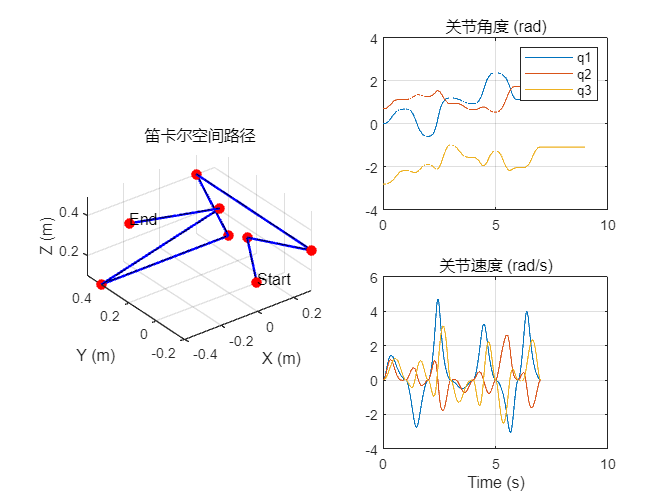


% --- 4.1 绘制轨迹验证图 ---
figure('Color', 'w', 'Name', '轨迹规划验证');
subplot(2,2,[1 3]);
plot3(total_pos(1,:), total_pos(2,:), total_pos(3,:), 'b-', 'LineWidth', 1.5); hold on;
plot3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 'ro', 'MarkerFaceColor', 'r');
plot3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 'k--', 'LineWidth', 0.5);
text(waypoints(1,1), waypoints(1,2), waypoints(1,3)+0.02, 'Start');
text(waypoints(end,1), waypoints(end,2), waypoints(end,3)+0.02, 'End');
grid on; axis equal; view(3); xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)'); title('笛卡尔空间路径');

subplot(2,2,2); plot(total_t, total_q); grid on; title('关节角度 (rad)'); legend('q1','q2','q3');
subplot(2,2,4); plot(total_t, total_dq); grid on; title('关节速度 (rad/s)'); xlabel('Time (s)');



% --- 4.2 导出仿真数据 (跨文件夹自动投送) ---
fprintf('>> 正在准备导出数据...\n');

>> 正在准备导出数据...



% 1. 安全检查：变量是否存在
if ~exist('out', 'var')
    fprintf(2, '❌ 错误：变量 "out" 不存在。请确保 STEP 3 仿真已成功运行。\n');
    return;
end

try
    % 2. 提取数据 (基于 Timeseries 格式)
    % 注意：如果您这里报错 "不支持点索引"，说明 Simulink 里 Save format 还是 Array，请改为 Timeseries
    t_sim = out.sim_q_actual_hope.Time;
    d_hope = out.sim_q_actual_hope.Data;
    d_rbf  = out.sim_q_actual_rbf.Data;
    d_pid  = out.sim_q_actual_pid.Data;
    
    % 整合数据
    data_export = [t_sim, d_hope, d_rbf, d_pid];
    
    % 3. 构建目标路径
    current_folder = pwd; 
    % 目标是兄弟文件夹 "Python Visualization"
    target_folder = fullfile(current_folder, '..', 'Python Visualization');
    
    % 4. 检查文件夹并获取绝对路径
    if isfolder(target_folder)
        % 获取文件夹的绝对路径 (解决 .. 符号问题)
        [~, info] = fileattrib(target_folder);
        final_folder_path = info.Name;
    else
        warning('⚠️ 未找到 "Python Visualization" 文件夹，数据将保存在当前目录。');
        final_folder_path = current_folder;
    end
    
    % 5. 拼接最终文件名
    file_name = 'robot_simulation_data.csv';
    final_full_path = fullfile(final_folder_path, file_name);
    
    % 6. 写入文件
    writematrix(data_export, final_full_path);
    
    % 7. 成功提示
    fprintf('✅ [成功] 数据导出完毕！\n');
    fprintf('📂 文件已保存至: %s\n', final_full_path);
    
catch ME
    fprintf(2, '❌ 数据导出失败: %s\n', ME.message);
    if strcmp(ME.identifier, 'MATLAB:dotNameOnNonScalar') || contains(ME.message, '索引')
        fprintf(2, '🔍 提示: 请检查 Simulink "To Workspace" 模块的 "Save format" 是否已设为 "Timeseries"\n');
    end
end

✅ [成功] 数据导出完毕！


📂 文件已保存至: C:\Users\ZLX\Documents\v2.0\3-DOF_Robotic_Arm_Dynamics_Simulation_and_Visualization_System\Python Visualization\robot_simulation_data.csv



disp('========================================');

disp('   所有任务执行完毕');

   所有任务执行完毕


disp('========================================');

function q = inverse_kinematics(x, y, z)
    % 机构参数
    d1 = 0.1; a2 = 0.4; a3 = 0.3;

    % 关节 1
    q1 = atan2(y, x);
    
    % 辅助变量
    r = sqrt(x^2 + y^2);
    z_eff = z - d1;
    D_sq = r^2 + z_eff^2;
    
    % 关节 3 (余弦定理)
    cos_q3 = (D_sq - a2^2 - a3^2) / (2 * a2 * a3);
    cos_q3 = max(min(cos_q3, 1), -1); % 数值保护，防止超出 [-1, 1]
    q3 = -acos(cos_q3); % 肘部向下/背部构型选择

    % 关节 2
    alpha = atan2(z_eff, r);
    k1 = a2 + a3 * cos(q3);
    k2 = a3 * sin(q3);
    q2 = alpha - atan2(k2, k1);

    q = [q1; q2; q3];
end